overall goal: for pt1left contact 1, get the zscore that describes how different each run is from one another...z score tells you how many standard deviations away from something a mean is...so....hmm

get average of all three runs, get the z score of that matrix? 

generate table with all the run data in it 

mastertab has patient, hemisphere, contact, and run data (9*6*2)

dir = readtable("PtDirectorySimple.xlsx");
mastertable = []; 
for i = 1:height(dir)
jsonFiles = dir.JsonSurvey{i};
side = dir.Hemisphere{i};
startIndex = dir.StartIndex(i);
num = num2str(dir.Patient(i));
hemi = upper(dir.Hemisphere(i));
js = jsondecode(fileread(jsonFiles));
outTABLE = extractSurveyData(js, side, startIndex);
pt = repmat({append("pt", num)}, 18, 1); 
outTABLE.patient = pt; 
mastertable = [mastertable; outTABLE]; 
end 


concept: for 02 of pt1 left, average the three runs into a single number each (across all frequencies) and then get the average and standard deviation of that number 

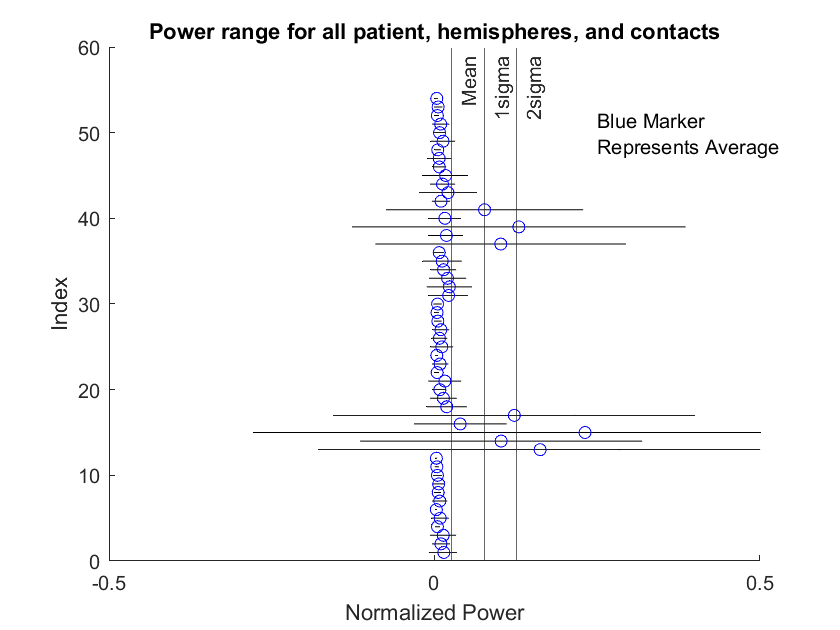

localtab = [];  
y = zeros(4096,3); 
mastertable2 = mastertable;
col = []; 
for x = 1:height(mastertable2) 
    temp = mastertable.PF_Data{x}; 
    col = [col; temp.Power]; 
end
normcol = normalize(col, 'range'); 
colm = reshape(col, 4096, height(mastertable2)); 

for x = 1:height(mastertable)
    mastertable2.PF_Data{x}.Power = colm(:,x);
end

for k = 1:height(mastertable2)
    %if we have the first run then we have that contact 
    if mastertable2.RunNum(k) == 1 
        t = mastertable2(k:k+2, :); %get all three runs for that contact
        for j = 1:3
            powerdata = t.PF_Data{j};
            y(:,j) = powerdata.Power; 
            runav = mean(powerdata.Power);%single av for all power data
            runavmat(j) = runav; %store in matrix 
        end
        ny1 = y(:); %takes y and makes it a column vector 
        %ny2 = normalize(ny1, 'range'); %makes it 0 to 1 
        ny3 = reshape(ny1, size(y)); %takes normalized data and reshapes to y 
        ny3 = mean(ny3,2); 
        runavall = mean(ny3); %average the average of all three runs, single number
        runst = std(ny3); %std dev of all three runs 
        new = mastertable(k, :); 
        new.PF_Data = []; 
        new.RunNum = []; 
        new.RunAvg = runavall; 
        new.RunStd = runst; 
        %new.avpwrdata = array2table(y); 
        localtab = [localtab; new];
    end
end

runarray = (localtab.RunAvg(1:6)); %averages for 1st patient, 1st hemisphere 
z = zscore(runarray);
runarray = (localtab.RunAvg(7:12));
z = zscore(runarray);
avarray = localtab.RunAvg; 
allmean = mean(avarray);
starray = localtab.RunStd; 
allstd = mean(starray);
minarray = avarray - starray; 
maxarray = avarray + starray;
y = [1:height(localtab); 1:height(localtab)]; 
x = transpose([minarray, maxarray]);
line(x,y, 'color', 'k', 'LineWidth', 0.5)
hold on
plot(avarray, y, 'bo', 'MarkerFaceColor', "none")
xlim([-0.5 0.5])
xline(allmean+allstd, '-', {'1sigma'}) %label this 
xline(allmean+2*allstd, '-', {'2sigma'})
xline(allmean, '-', {'Mean'})
xlabel("Normalized Power")
ylabel("Index")
title("Power range for all patient, hemispheres, and contacts")
text(0.25, 50, {'Blue Marker', 'Represents Average'})

sum(allmean+allstd>maxarray)

ans = 46

%define exceeding as average exceeds, color it red, only do 1 std 
%("10% exceed 1 std of average) using text 

mat = [1 2 1; 4 9 6; 2 8 9]; 
z= zscore(mat, 0, 2)

z =    -0.5774    1.1547   -0.5774
   -0.9272    1.0596   -0.1325
   -1.1446    0.4402    0.7044
